clc,clear,close all

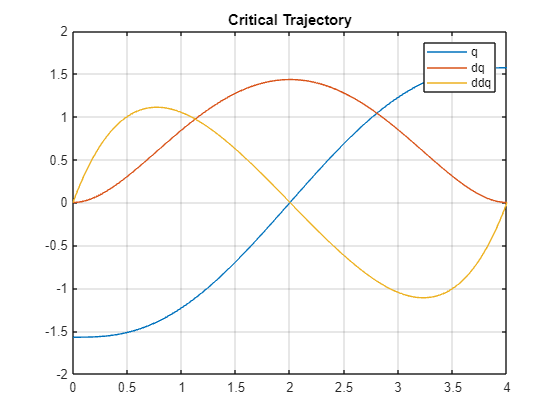

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [54e-6, 54e-6]; %[kg/m^2]
kr = [1/10,1/5];
%kr = [1,1];

%{
% link dimension
lx=[0.20 0.20]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m
%}

% link dimension
lx=[0.25 0.25]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m



%material properties
density=2660; % [kg/m3] AW 5083 alloy
%rho=(density*1000)/100^3; %[g/cm3]
rho = density; 

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
qd = [];

for i=1:length(t)
    qd=[qd;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

figure
plot(t, qd);
legend('q', 'dq','ddq');
title('Critical Trajectory');
grid on;


% TODO: Friction?
F = [0.01 0; 0 0.01]; % TEMP

% Initial Values

q0 = [-pi/2;-pi/2];
dq0 = [0;0];
ddq0 = [0;0];

%controller variables
%Kp = diag([ 15 15 ]);
%Kd = diag([ 32 32 ]);

val=[1 1];
Kp=diag((val.^2)./2);
Kd=diag(val);
%wry 

[Bq, Cq, gq, q, dq] = methods.dyn(lx,ly,lz,rho,mm,Im,kr)

$$Bq = \begin{array}{l} \left(\begin{array}{cc} \frac{399\,\cos\left(q_{1}+2\,q_{2}\right)}{16000}+\frac{399\,\cos\left(q_{1}+q_{2}\right)}{3200}+\frac{4191\,\cos\left(q_{1}\right)}{16000}+\frac{1197\,\cos\left(q_{2}\right)}{16000}+\frac{96507426617796165710597}{590295810358705651712000} & \sigma_{1}\\ \sigma_{1} & \frac{1197\,\cos\left(q_{1}+q_{2}\right)}{16000}+\frac{1197\,\cos\left(q_{1}\right)}{8000}+\frac{399\,\cos\left(q_{2}\right)}{16000}+\frac{8604942728174374274309}{147573952589676412928000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{399\,\cos\left(q_{1}+2\,q_{2}\right)}{32000}+\frac{399\,\cos\left(q_{1}+q_{2}\right)}{4000}+\frac{1197\,\cos\left(q_{1}\right)}{8000}+\frac{399\,\cos\left(q_{2}\right)}{8000}+\frac{16805906188353087057}{288230376151711744000} \end{array}$$

$$Cq = \begin{array}{l} \left(\begin{array}{cc} -\frac{{\mathrm{dq}}_{2}\,\left(\frac{399\,\sigma_{2}}{16000}+\frac{\sigma_{1}}{8000}+\frac{399\,\sin\left(q_{2}\right)}{8000}\right)}{2} & -\frac{399\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(\sigma_{2}+2\,\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{2}\right)\right)}{32000}\\ {\mathrm{dq}}_{1}\,\left(\frac{399\,\sigma_{2}}{32000}+\frac{\sigma_{1}}{16000}+\frac{399\,\sin\left(q_{2}\right)}{16000}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=399\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=\sin\left(q_{1}+2\,q_{2}\right) \end{array}$$

$$gq = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

$$dq = \left(\begin{array}{c} {\mathrm{dq}}_{1}\\ {\mathrm{dq}}_{2} \end{array}\right)$$

vpa(Bq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} 0.024938\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.12469\,\cos\left(q_{1}+q_{2}\right)+0.26194\,\cos\left(q_{1}\right)+0.074812\,\cos\left(q_{2}\right)+0.16349 & \sigma_{1}\\ \sigma_{1} & 0.074812\,\cos\left(q_{1}+q_{2}\right)+0.14962\,\cos\left(q_{1}\right)+0.024938\,\cos\left(q_{2}\right)+0.058309 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.012469\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.09975\,\cos\left(q_{1}+q_{2}\right)+0.14962\,\cos\left(q_{1}\right)+0.049875\,\cos\left(q_{2}\right)+0.058307 \end{array}$$

vpa(Cq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} -0.5\,{\mathrm{dq}}_{2}\,\left(0.024938\,\sigma_{1}+0.049875\,\sin\left(q_{1}+q_{2}\right)+0.049875\,\sin\left(q_{2}\right)\right) & -0.012469\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(\sigma_{1}+2.0\,\sin\left(q_{1}+q_{2}\right)+2.0\,\sin\left(q_{2}\right)\right)\\ {\mathrm{dq}}_{1}\,\left(0.012469\,\sigma_{1}+0.024938\,\sin\left(q_{1}+q_{2}\right)+0.024938\,\sin\left(q_{2}\right)\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+2.0\,q_{2}\right) \end{array}$$